# Lab 7 - Hermite Interpolation

## 3 - Probleme

x = [1.3; 1.6; 1.9];
y = [0.6200860; 0.4554022; 0.2818186];
y1 = [-0.5220232; -0.5698959; -0.5811571];
[Q, H] = HermiteInterpolation(x, y, y1);
syms x_sym
Q

Q =     0.6201         0         0         0         0         0
    0.6201   -0.5220         0         0         0         0
    0.4554   -0.5489   -0.0897         0         0         0
    0.4554   -0.5699   -0.0698    0.0664         0         0
    0.2818   -0.5786   -0.0291    0.0680    0.0027         0
    0.2818   -0.5812   -0.0085    0.0686    0.0010   -0.0028


fprintf("%.15f\n", subs(H, x_sym, 1.5));

0.511827701728395


### 2


$$f(x) = sin(x)$$


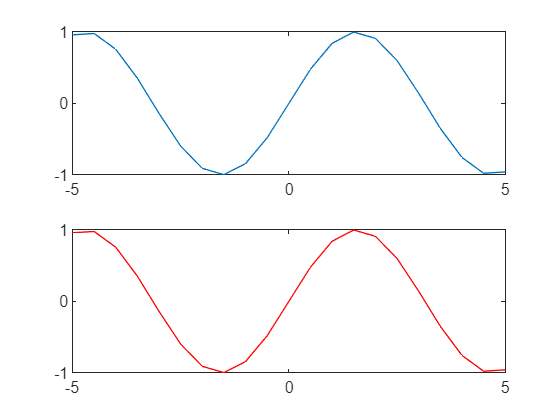

clear;
syms x_sym;
f = sin(x_sym);
df = diff(f, x_sym, 1);
fn = matlabFunction(f);
fn1 = matlabFunction(df);
x = -5:0.5:5;
y = fn(x);
y1 = fn1(x);
figure;

subplot(2, 1, 1);
xlabel('x');
ylabel('sin(x)');
plot(x, y);
hold on;

subplot(2, 1, 2);
xlabel('x');
ylabel('H(x)');
title('H(x)');
[Q, H] = HermiteInterpolation(x, y, y1);
fnH = matlabFunction(H);
yH = fnH(x);
plot(x, yH, 'r');

### 3 


$$f(x) = log(x)$$


clear;
syms x_sym;
f = log(x_sym);
df = diff(f, x_sym, 1);
fn = matlabFunction(f);
fn1 = matlabFunction(df);
x = [20; 30];
xx = 1:5:50;

y = fn(x);
yy = fn(xx);

y1 = fn1(x);
[Q, H] = HermiteInterpolation(x, y, y1);
fnH = matlabFunction(H);
yH = fnH(x);
yyH = fnH(xx);

figure;

subplot(2, 1, 1);
xlabel('x');
ylabel('sin(x)');
plot(x, y, 'o-');
hold on;
plot(xx, yy, 'b');

subplot(2, 1, 2);
xlabel('x');
ylabel('H(x)');
title('H(x)');
[Q, H] = HermiteInterpolation(x, y, y1);
Q

Q =     2.9957         0         0         0
    2.9957    0.0500         0         0
    3.4012    0.0405   -0.0009         0
    3.4012    0.0333   -0.0007    0.0000


H

$$H = \frac{x_{\mathrm{sym}}}{20}-\frac{4359652391911219\,{\left(-20+x_{\mathrm{sym}}\right)}^{2}}{4611686018427387904}+\frac{103316141977679\,{\left(-20+x_{\mathrm{sym}}\right)}^{2}\,\left(-30+x_{\mathrm{sym}}\right)}{4611686018427387904}+\frac{4493989561754513}{2251799813685248}$$

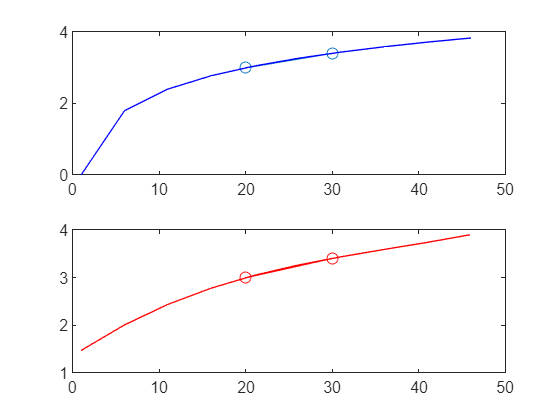

fnH = matlabFunction(H);
yH = fnH(x);
plot(x, yH, 'ro-');
hold on;
plot(xx, yyH, 'r');

## 4 - Probleme practice

### 1

clear;
syms x_sym;
f = exp(x_sym);
df = diff(f, x_sym, 1);
fn = matlabFunction(f);
fn1 = matlabFunction(df);

x = [0, 1, 2];
y = fn(x);
y1 = fn1(x);

[Q, H] = HermiteInterpolation(x, y, y1);
fnH = matlabFunction(H);
x_test = [0.25];
y_test = fnH(x_test);
x_test

x_test = 0.2500

for i = 1:length(x_test)
    fprintf("Hermite polynomial value: %.15f\n", y_test(i));
end

Hermite polynomial value: 1.283645099219907


[p, l] = LagrangeInterpolation(x, y);
y_lagrange = p(x_test);
for i =1:length(x_test)
    fprintf("Lagrange polynomial value: %.15f \t abs(H - L) = %.15f\n", y_lagrange(i), abs(y_test(i) - y_lagrange(i)));
end

Lagrange polynomial value: 1.152774290676084 	 abs(H - L) = 0.130870808543823


for i = 1:length(x_test)
    fprintf("computer value: %.15f \t abs(H - Computer) = %.15f\n", exp(x_test(i)), abs(y_test(i) - exp(x_test(i))));
end

computer value: 1.284025416687741 	 abs(H - Computer) = 0.000380317467835


### 2

clear;
syms x_sym;
f = sin(x_sym);
df = diff(f, x_sym, 1);
fn = matlabFunction(f);
fn1 = matlabFunction(df);
x = [0.3, 0.32, 0.35];
y = fn(x);
y1 = fn1(x);

[Q, H] = HermiteInterpolation(x, y, y1);

fnH = matlabFunction(H);

x_test = 0.34;
y_test_real = fn(x_test);
y_test_hermite = fnH(x_test);
fprintf("x = %f \t sin(x) = %.15f \t H(x) = %.15f \t err = %.15f\n", x_test, sin(x_test), fnH(x_test), abs(sin(x_test) - fnH(x_test)));

x = 0.340000 	 sin(x) = 0.333487092140814 	 H(x) = 0.333487092140843 	 err = 0.000000000000028


clear;
syms x_sym;
f = sin(x_sym);
df = diff(f, x_sym, 1);
fn = matlabFunction(f);
fn1 = matlabFunction(df);
x = [0.3, 0.32, 0.33, 0.35];
y = fn(x);
y1 = fn1(x);

[Q, H] = HermiteInterpolation(x, y, y1);

fnH = matlabFunction(H);

x_test = 0.34;
y_test_real = fn(x_test);
y_test_hermite = fnH(x_test);
fprintf("x = %f \t sin(x) = %.15f \t H(x) = %.15f \t err = %.15f\n", x_test, sin(x_test), fnH(x_test), abs(sin(x_test) - fnH(x_test)));

x = 0.340000 	 sin(x) = 0.333487092140814 	 H(x) = 0.333487092140814 	 err = 0.000000000000000


### 3


$$\nu(t) = \frac{ds(t)}{dt} \\
s(t) - distance \ at \ time \ t$$


x = [0, 3, 5, 8, 13];
y = [0, 225, 383, 623, 993];
y1 = [75, 77, 80, 74, 72];

[Q, H] = HermiteInterpolation(x, y, y1);
diffH = diff(H, x_sym, 1);

fnH = matlabFunction(H);
fnH1 = matlabFunction(diffH);

x_test = 10;
fprintf("t = %d \t distance = %.15f \t velocity = %.15f\n", x_test, fnH(x_test), fnH1(x_test));

t = 10 	 distance = 742.502839098771005 	 velocity = 48.381736363981247
